# Lead-lag compensator design using phase margins

This livescript is a brief manual in support of the app on how to do lead compensator design using frequency response methods, or specifically, by managing the phase margin and cross over frequency as viewed in a Bode diagram. The aim is to help users understand core principles and steps, after which they may prefer to use ***sisotool*** or other means to undertake designs on systems of their own choosing.

A logical supporting file is ***lead_design_with_bode.mlx*** which gives more comprehensive background and MATLAB source code alongside some examples. 

### Similar files and the toolbox

See website below for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox](https://sites.google.com/sheffield.ac.uk/controleducation/matlabresources/community-control-toolbox)

This group of files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

**For more information on those files  uncomment and run either line of the code below (using run section):**

% doc Control101 Toolbox  % this line works even if toolbox not installed
%
% help control101  % this line only works if the toolbox is installed

File written by J.A.Rossiter, University of Sheffield                         

## Table of Contents

- Technical and mathematical background

- Simple gain design using phase margin criteria and use of the app

## 1. Technical and mathematical background

This script assumes the following block diagram with system *G(s*) and compensator *M(s)*.

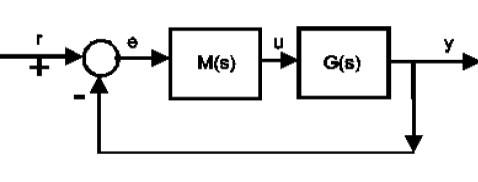

Readers should be familar with the file  **proportional_design_with_bode.mlx  **and/or** proportional_design_phase_margin.mlapp **for background on performance specifications which underpin design and also because a similar process is a first step in a lead compensator design. Also, a lead-lag design makes use of the steps and principles used in both:

***lead_design_with_bode.mlx   and ***  ***lag_design_with_bode.mlx*** (as well as the related apps ***lead_design_phase_margin*** and ***lag_design_phase_margin***).

%%%%%%  REMOVE COMMENTS TO RUN THE CODE AND OPEN THE RELEVANT TOOLBOX FILES
% proportional_design_with_bode
% proportional_design_phase_margin  
% lead_design_with_bode
% lead_design_phase_margin
% lag_design_with_bode
% lag_design_phase_margin

The closed-loop transfer function is:   $G_c =\frac{\textrm{GM}}{1+\textrm{GM}}$ and the intention is to design the compensator M(s) to have the following stucture where*** K*** is a simple proportional.


$$M\left(s\right)=K\left(\frac{s+a}{s+a\alpha }\right)\left(\frac{s+b\beta }{s+b}\right),\;\;\;\;\;\alpha >1,\;\beta >1,a>b$$
      

The component $K\left(\frac{s+a}{s+a\alpha }\right)$ is a lead and the component $\left(\frac{s+b\beta }{s+b}\right)$ is a lag.

Core properties of the lead component are that  low frequency gain is '$\alpha$' times smaller than the high frequency gain and secondly, the system has positive phase in the regions near the corner frequencies: ***a, a***$\alpha$. In order for make most use of the phase characteristic, the corner frequencies are chosen to bridge the desired gain cross over frequency $w_c$ and a scaling factor is added to make the 'gain' of the dynamic part unity at this frequency. Hence the lead component takes the structure:  

$M\left(s\right)\;=\;K_p \;\left\lbrack \sqrt{\alpha }\;\left(\frac{s+\frac{w_c }{\sqrt{\alpha }}}{s+w_c \sqrt{\alpha }}\right)\right\rbrack$ ;                    $1\le \alpha \le 10$.

The lag component has the main property that the low frequency gain is a factor $\beta$ higher than the high frequency gain but it introduces negative phase around its corner frequencies. Consequently the largest of these, that is the zero, is chosen to be a decade below the cross-over frequency $w_c$.

## 2. Lead-lag compensator design steps and use of the app

For slower and detailed explanations and more flexible code and examples, see the toolbox file:

%% UNCOMMENT TO OPEN THIS FILE
% lead_lag_design_with_bode

Here we assume  the design is based on specifications:

- Desired bandwidth (for simplicity of design the gain cross over frequency is used as a rough equivalent).

- Desired PM

- Designed offset/low frequency gain.

A simple lead-lag design can be determined mechanistically to meet all 3 design criteria precisely, assuming of course these are feasible. To do this we undertake 3 separate mechanistic designs in order to meet the criteria one at a time. Subsequent steps need to be done in such a way as to preserve the already achieved criteria.

**Remark**: The app is primarily for illustrative purposes of the core design steps and thus only allows integer values of $\alpha ,\;\beta$ and simple choices for other variables. If a user wants to meet criteria precisely (largely irrelevant for practical systems and control), they would need to do the relevant computations within MATLAB or sisotool as shown in ***lead_lag_design_with_bode***.

### 2.1 Simple gain design to meet the bandwidth criteria

**Warning**: For this step, ensure the pole/zero ratio is one for both the lead and lag as during  step 1 we do not want either of the lead or lag components.

We want to design the gain $K_p$ of the compensator the ***M(s)*** so that we have a desirable gain cross over frequency $w_c$. The process is analaogous to the gain designs used for simple proportional design. In essence the gain $K_p$ is selected to meet the criteria:


$$\left|G\left(jw_c \right)\right|K_p =1$$


This can be done by an iteration of the  simple scaling on the gain plot and determining the implied cross over frequency visually as this aids insight into the process. However,  explicit computation is straightforward. Alternatvely, the 'overlay several $K_p$ ' button allows a quick view of how the cross-over frequency changes so one can quickly find a suitable value for $K_p$. The app draws a vertical line (dotted green) at the target cross over frequency so the user can see when the gain plot. 

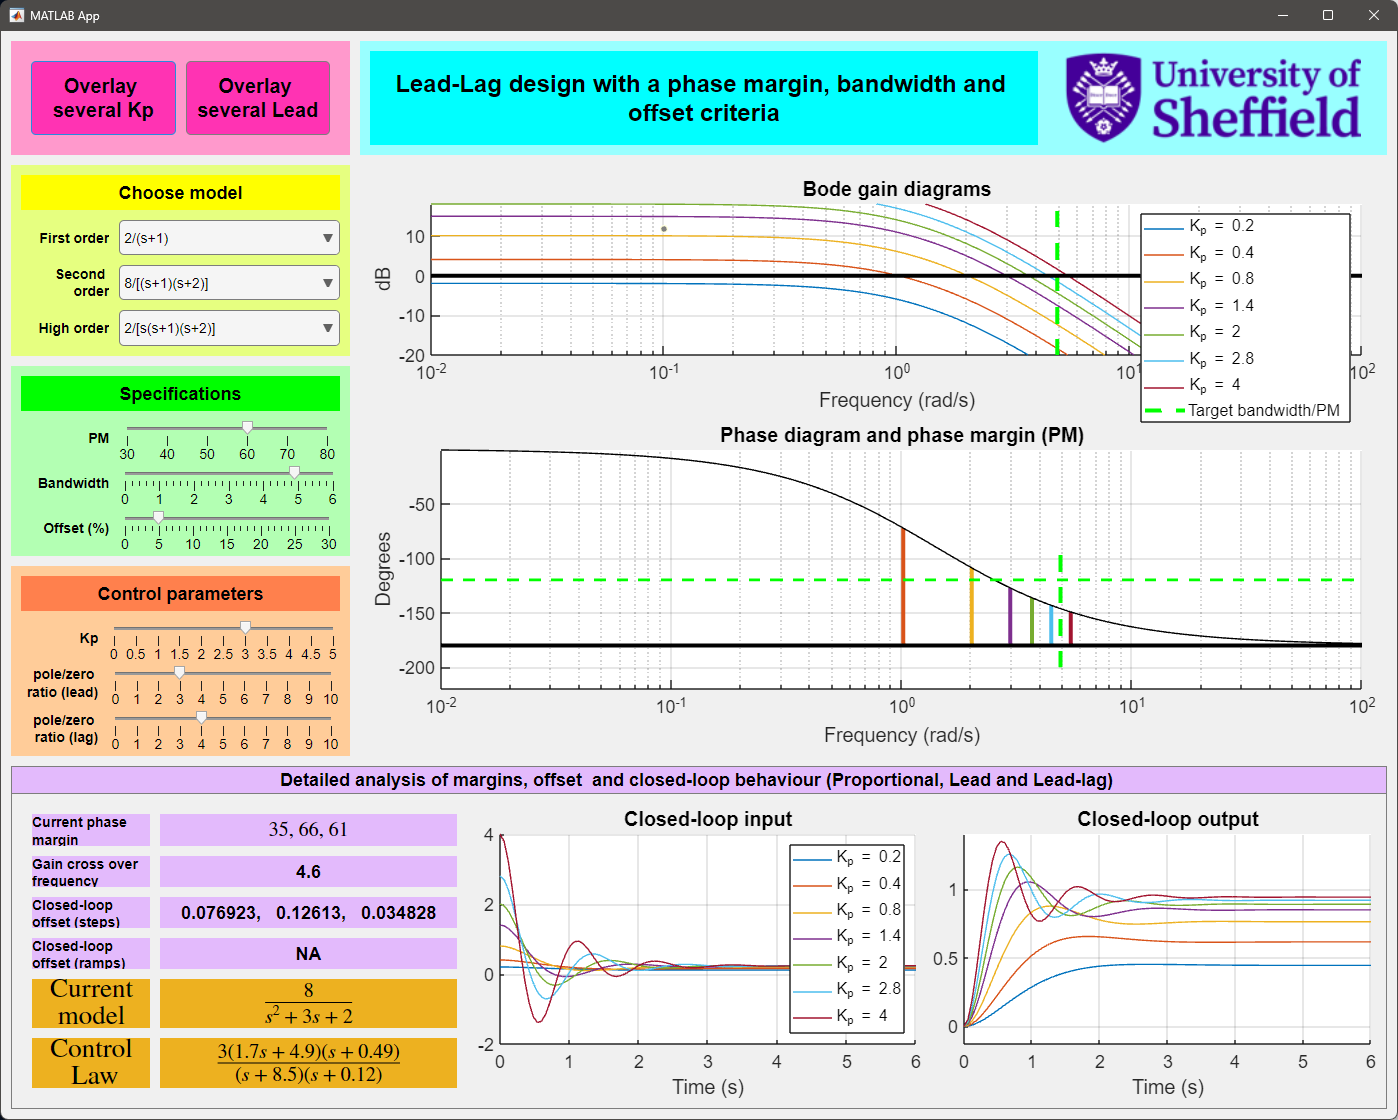 

A more precise value of $K_p$ selected by the slider and the plot is updated to show this alongside the corresponding phase margin and cross-over frequency. 

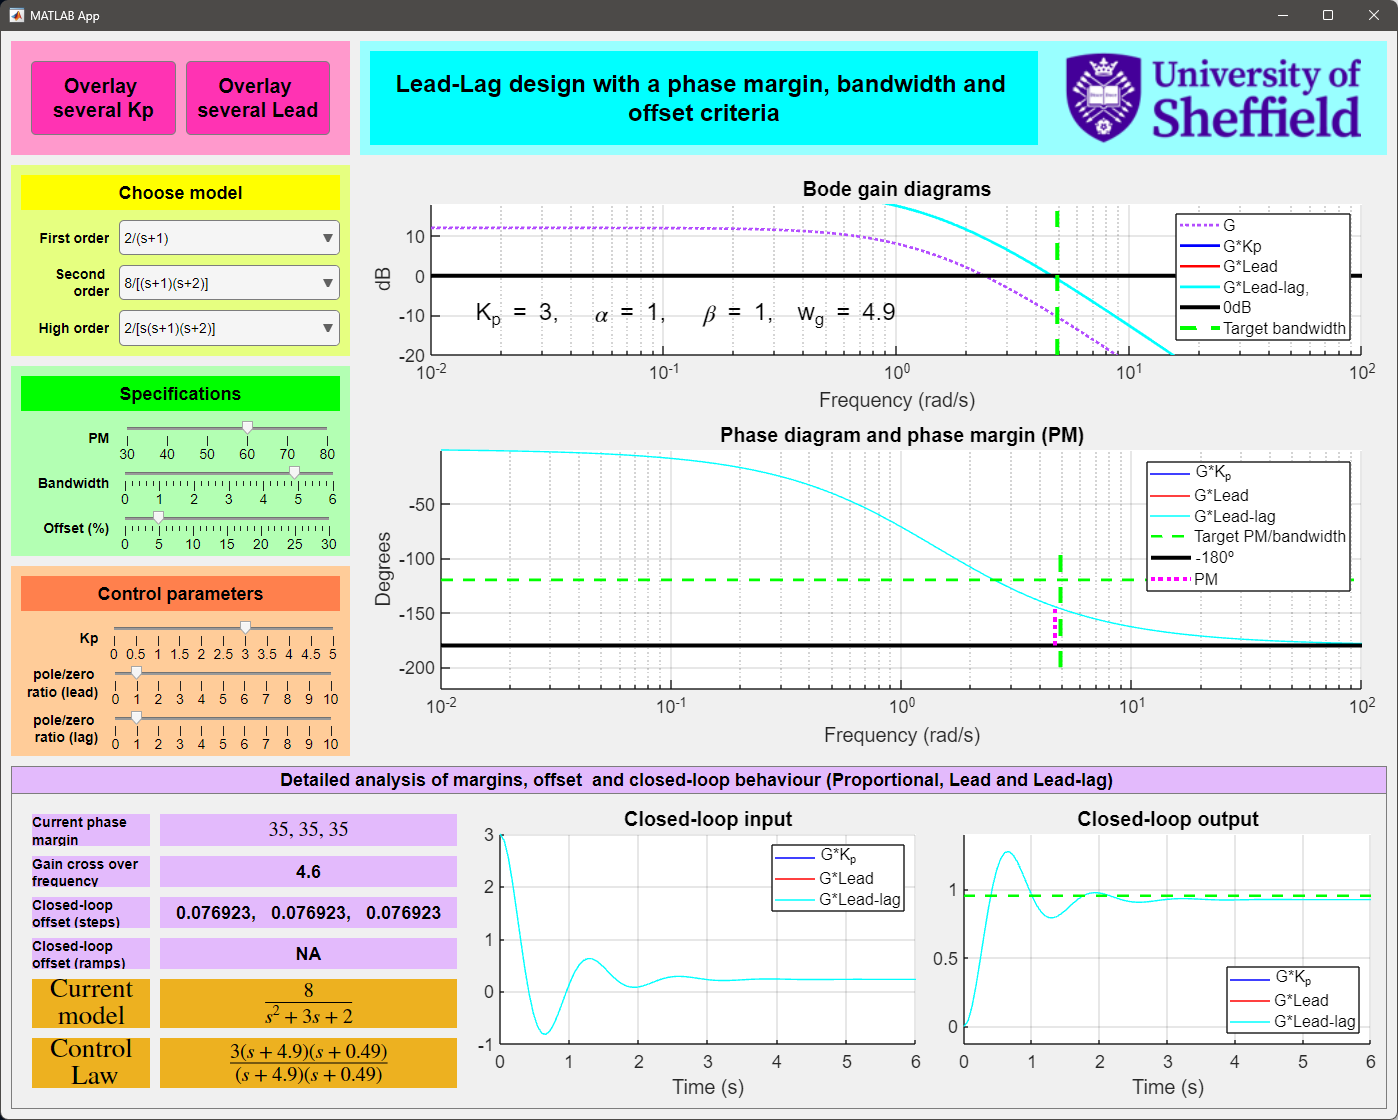

### 2.2 Adding the phase margin criteria

Having chosen the proportional gain, we add the lead component  $\;\left\lbrack \sqrt{\alpha }\;\left(\frac{s+\frac{w_c }{\sqrt{\alpha }}}{s+w_c \sqrt{\alpha }}\right)\right\rbrack$   to improve the phase margin. In the screen dump above it is clear that the current PM is only 35 and thus some positive phase rotation is needed (here the desired PM is set at 60 so a rotation of 25 is required).  It is known that the phase rotation $\phi$ provided by the dynamic component is given by the formulae $\alpha =\frac{\sin \left(\phi \right)+1}{1-\sin \left(\phi \right)}$, and thus the pole-zero ratio $\alpha$ can be determined explicity, if the required phase rotation $\phi$ is known. For simplicity the app only allows integer choices of $\alpha$ so some approximation will be inevitable.

With the app, the user is also encouraged to investigate different values for the pole-zero ratio $\alpha$ using the 'overlay several lead' button. It will be clear that changing $\alpha$ has not changed the cross-over frequency (see the gain plot) but does change the phase margin. The user can now identify by eye what will be a reasonable value of $\alpha$.

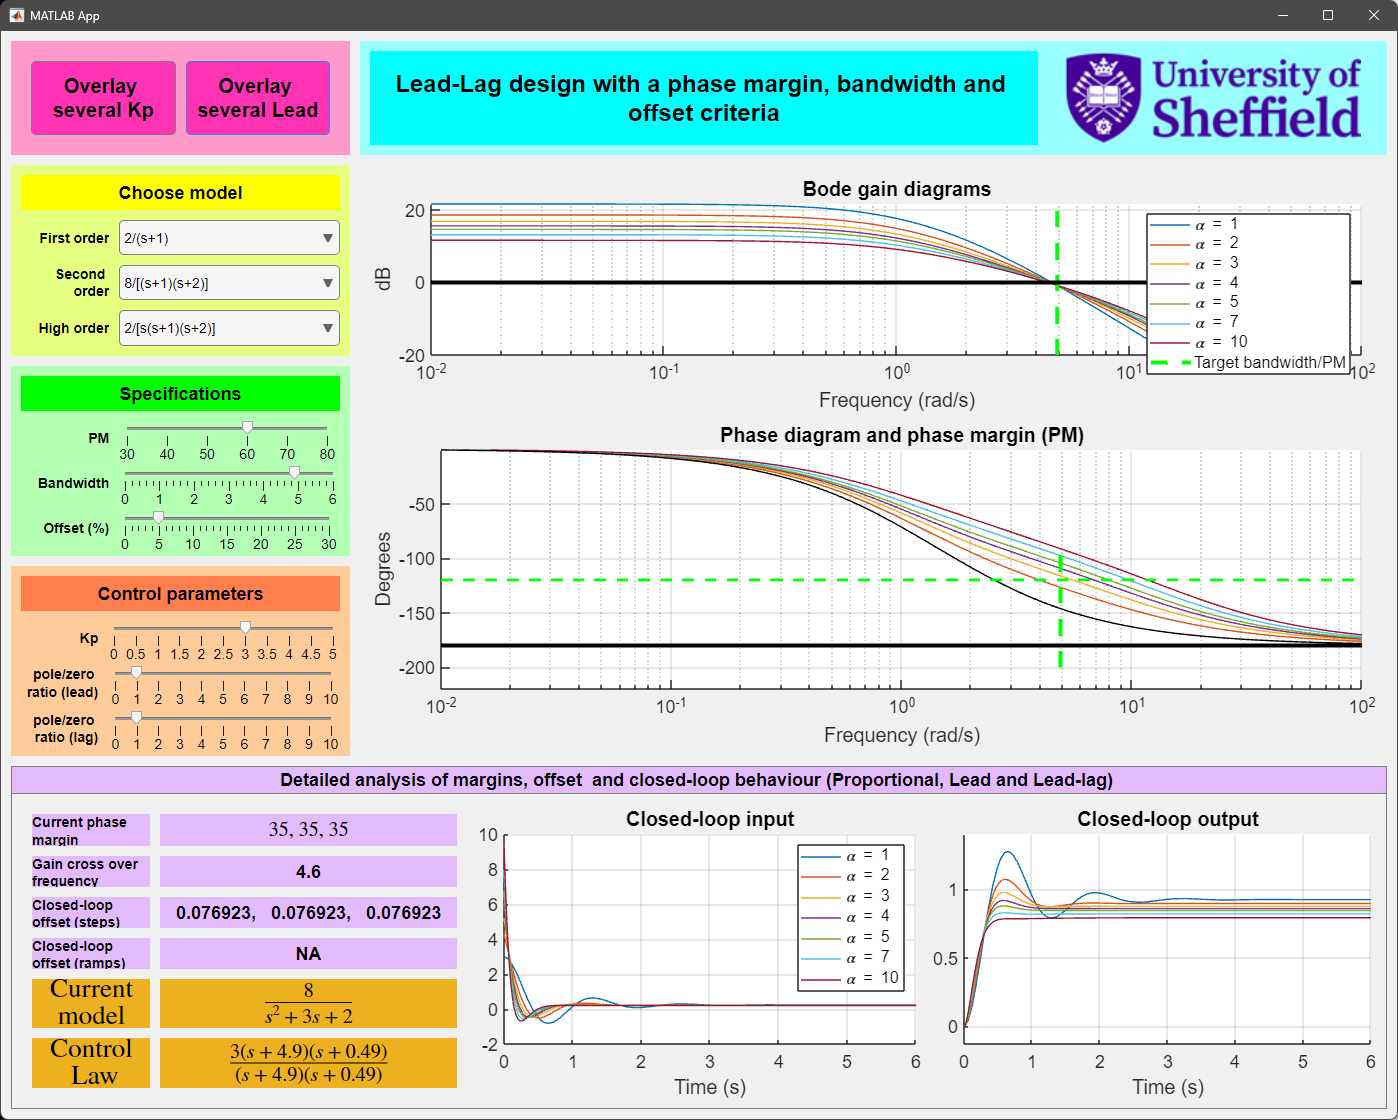

A specific choice of $\alpha$ is made using the slider for the lead. The plots are then updating so the user can check if they have achieved what they expect. For the example in the figure a value of $\alpha =3$ about is appropriate and gives close to a 60 degree PM as requested (non-integer values are required to be more precise) while retaining the desired cross-over frequency.

**Remark**:  The phase margins with just proportional and with the lead are given, respectively, in the text boxes in the bottom left, as well as the actual gain cross-over frequency, which may differ from the desired cross-over frequency if $K_p \;$is not well chosen or precise enough (again the app rounds numbers for convenience and thus small differences are visible and thus illustrate the concepts within the design approach).

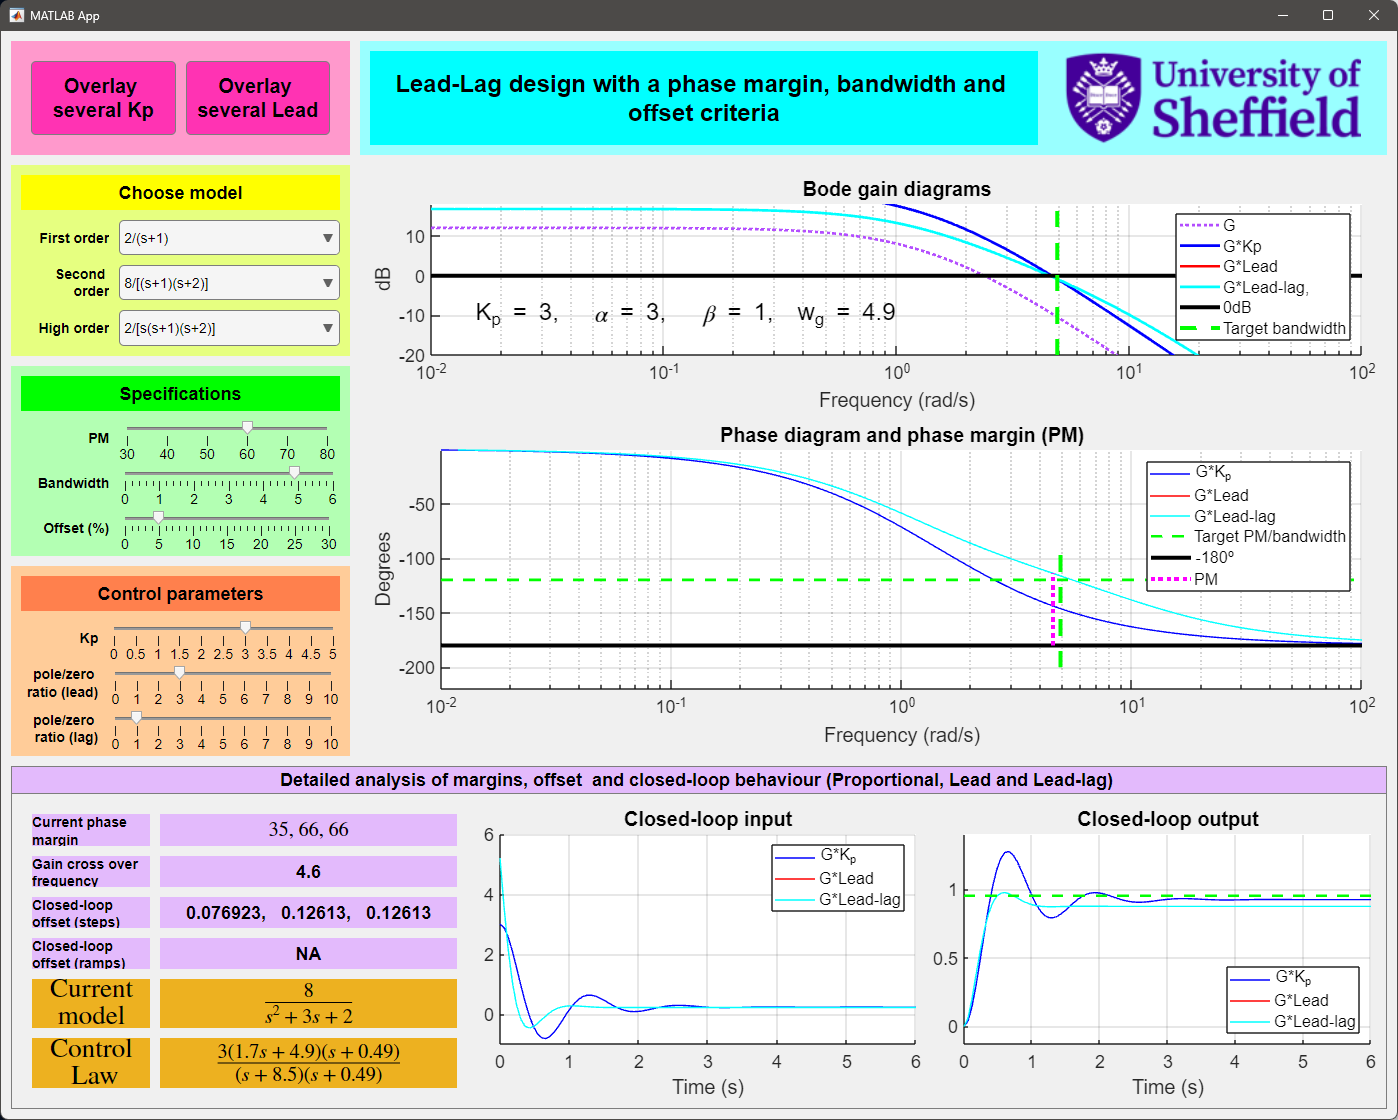

### 2.3  Offset criteria

**Offset to steps**: For a simple fbk loop with system G(s) and compensator M(s) and no integrator, offset to a constant unity reference is given by the formula: $e_{\textrm{ss}} =\frac{1}{1+G\left(0\right)M\left(0\right)}$.  

**Offset to ramps** can also be useful and is commonly used in books to help create more precise criteria to enable systematic/explicit design.This formula is only useful if the system DOES include an integrator. Offset to a unit ramp is given as: $e_{\textrm{ramp}} =\lim_{s\longrightarrow 0} \frac{1}{\textrm{sG}\left(s\right)M\left(s\right)}$

A lead does not deal with low frequency gain criteria explicity and thus finally the lag component is added to deal with this criteria. The formula required to determine the offsets are standard as shown here and thus the user can find the required value of $\beta$ explicitly, should they so desire (as shown in the earlier files, e.g. on proportional gain design or lag design). With the app, the user is able to use trial and error by changing $\beta$ using the slider and observing the impact on the step responses (bottom figures) and actual offsets which are given in the text boxes in the bottom left for completeness. It is clear that adding the lag has reduced the offset, but at a small cost to the PM criteria.